x = [0.05, 0.16, 0.27, 0.37, 0.41, 0.59, 0.80, 0.70, 0.95, 1.00];
y = [10.90, -85.5, -60.00, -44.50, -29.40, -27.50, -15.50, -21.50, -8.60, -17.70];

n = length(x)

n =     10


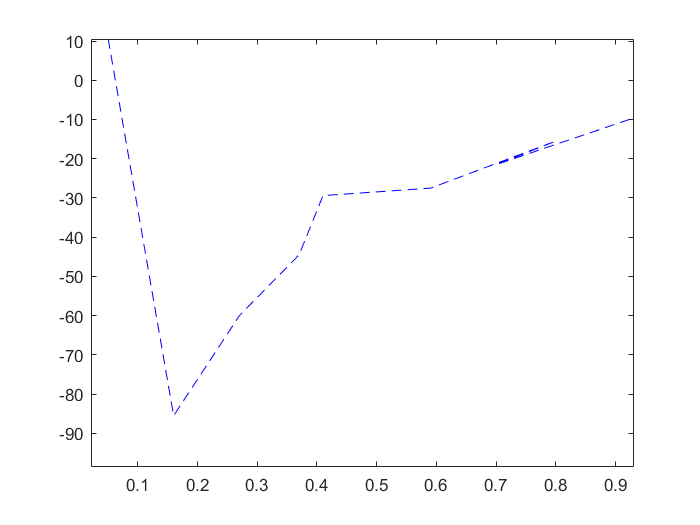

a = 1;
b = 2;

xx = [];

F1 = @(x) cos(5*x^2 - 3*x +10);
plot(x, y, 'b--');


Lagrange(F1, xx, n)

интерполяционный многочлен Лагранжа
   1.0e+18 *

  Columns 1 through 5

  -1.021001010085844  -0.000000066406992  -0.000000000000000                   0                   0

  Columns 6 through 10

                   0                   0                   0                   0                   0



ans = 	1.0e+18 *

  -1.021001010085844  -0.000000066406992  -0.000000000000000                   0                   0                   0                   0                   0                   0                   0


plot(Lagrange(F1, xx, n))

Error using Kovkel_POIT_4_L2>Lagrange
Too many input arguments.

function answer_for_lagrange  = Lagrange(F, xx, n)
l = 1;
x = a:(a-b)/n:b;
y = F(x);
answer_for_lagrange = 0;
for i = 1:n+1
    for j = 1:n+1
        if j~=i 
            l = l.*(xx -xx(j))/(x(i)-x(j));
        end
    end
    answer_for_lagrange = answer_for_lagrange + y(i)*l;
end
disp('интерполяционный многочлен Лагранжа');
disp(answer_for_lagrange);
end